# Модель толкателя

syms F(t);
F(t)=-(heaviside(t)-heaviside(t-0.2))*5*(1-cos(4*pi*2.5*t))

$$F(t) = -\left(5\,\mathrm{heaviside}\left(t-\frac{1}{5}\right)-5\,\mathrm{heaviside}\left(t\right)\right)\,\left(\cos\left(10\,\pi \,t\right)-1\right)$$

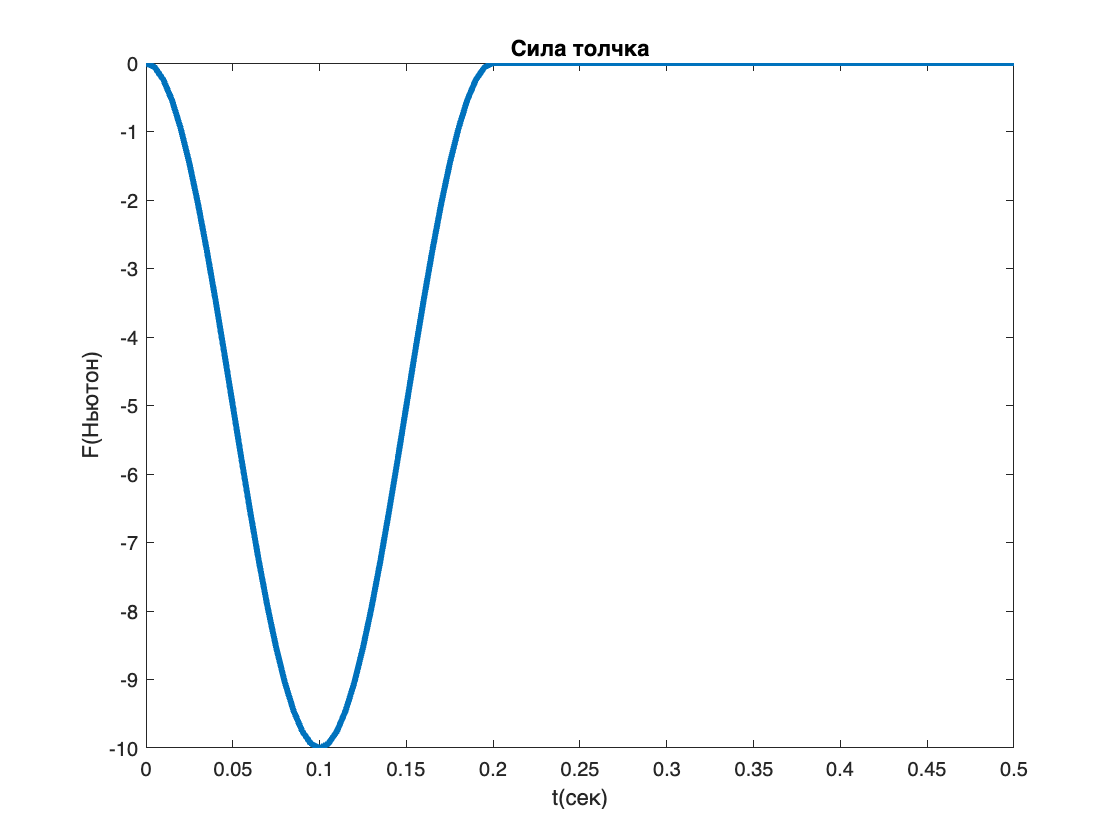

t=0:0.005:0.5;
plot(t,F(t),'LineWidth',3);title("Сила толчка");xlabel('t(сек)');ylabel("F(Ньютон)")

# Поиск p и c

m=74; g=9.81;l=0.88;
J=1/3*m*l^2;%момент инерции тела
syms p c
b=0.6;
p=double(solve(p/J==2*b,p,'Real',true))

p = 22.9222

c=double(solve((c-m*g*l)/J==(2*pi*0.3)^2-b^2,c,'Real',true))

c = 699.8206

# Уравнение движения

## 
$$\[
J\ddot{\theta}=mgl\theta+M-Fl
\]
\[
J\ddot{\theta}=mgl\theta-C\theta-P\dot\theta-Fl
\]
\[
J\ddot{\theta}+P\dot\theta+\theta(C-mgl)+Fl=0
\]

\[
\ddot{\theta}+\frac{P}{J}\dot\theta+\theta\frac{(C-mgl)}{J}+\frac{Fl}{J}=0
\]
$$


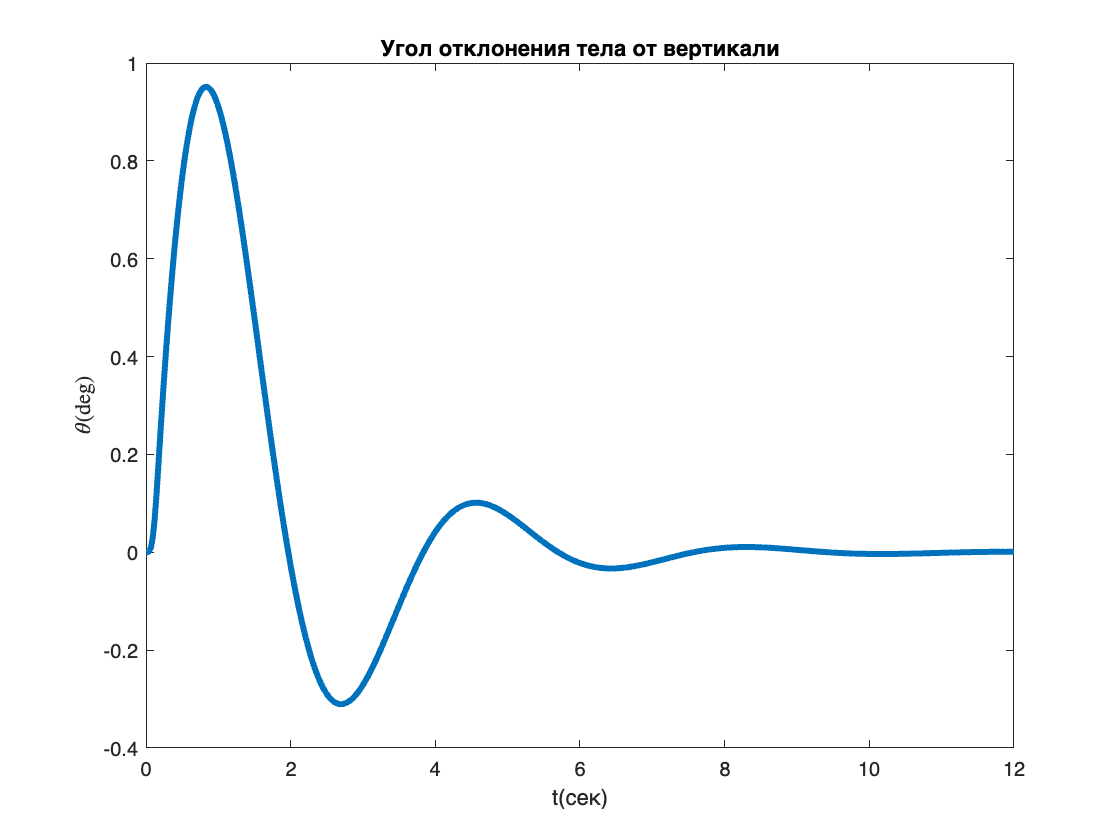

syms y(t);
Dy = diff(y,t);
cond = [y(0)==0, Dy(0)==0];
eqn = diff(y,t,2)+p/J*diff(y,t)+(c-m*g*l)*y/J+F(t)*l/J==0;
theta(t) = dsolve(eqn,cond);%theta

dtheta=diff(theta,1);

ddtheta=diff(dtheta,t);


% t=0:0.04:12;
t=linspace(0,12,512);


plot(t,rad2deg(theta(t)),'LineWidth',3);
title("Угол отклонения тела от вертикали");
xlabel("t(сек)");ylabel('$\theta$(deg)','Interpreter','latex')

# Сагиттальное движение центра масс

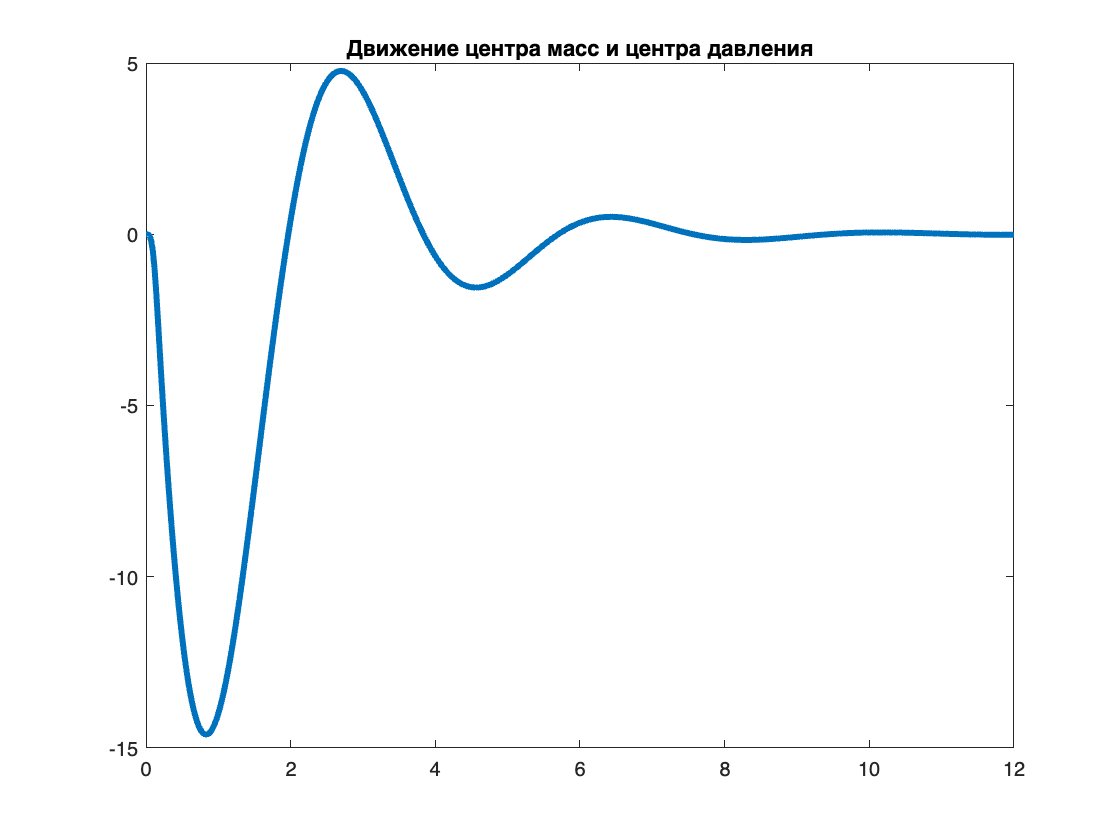

realeta=-l*double(theta(t))*1000;
plot(t,realeta,'LineWidth',3);
title("Движение центра масс и центра давления");
hold on;

% xlabel("t(сек)");ylabel('$\eta$(mm)','Interpreter','latex')

# Поиск Y, зная \eta

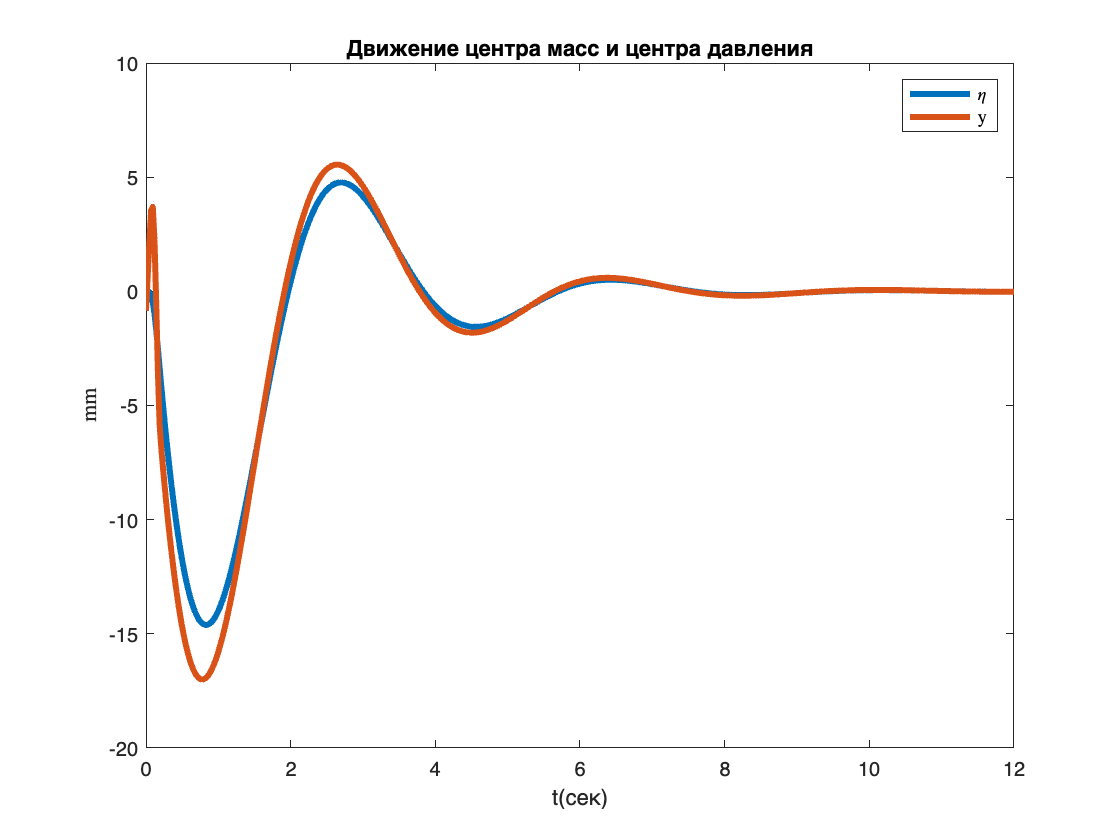

hp=0.07*(1+l*2);
yy=-l*(theta-(J+m*l*hp)/(m*g*l)*ddtheta)+F*(l+hp)/(m*g);

plot(t,fillmissing(double(yy(t)*1000),'linear'),'LineWidth',3);

xlabel("t(сек)");ylabel('mm','Interpreter','latex')
legend('$\eta$','y','Interpreter','latex')
hold off

# Поиск \eta, зная Y через FFT

% ybase=fillmissing(double(yy(t)*1000),'linear');
% пусть yy(t) это идеальные показания с датчиков
% ybase2=fillmissing(double(yy(t)-F(t)*(l+hp)/(m*g)*1000),'linear');
ybase2=fillmissing(double(yy(t)*1000),'linear');
ticks=512

ticks = 512


ycorrected=double(ybase2-1000*F(t)*(l+hp)/(m*g));
ybase2=ycorrected;

h=l*2;
hp = 0.07 * (1 + h);
J = m * l^2 / 3 + hp * m * l;
mgh=m*g*h;

fur2=@COPMfftfilt;
afterfur2=COPMfftfilt(ybase2',ticks,J,mgh);



# Оценка ошибки при восстановлении \eta через FFT

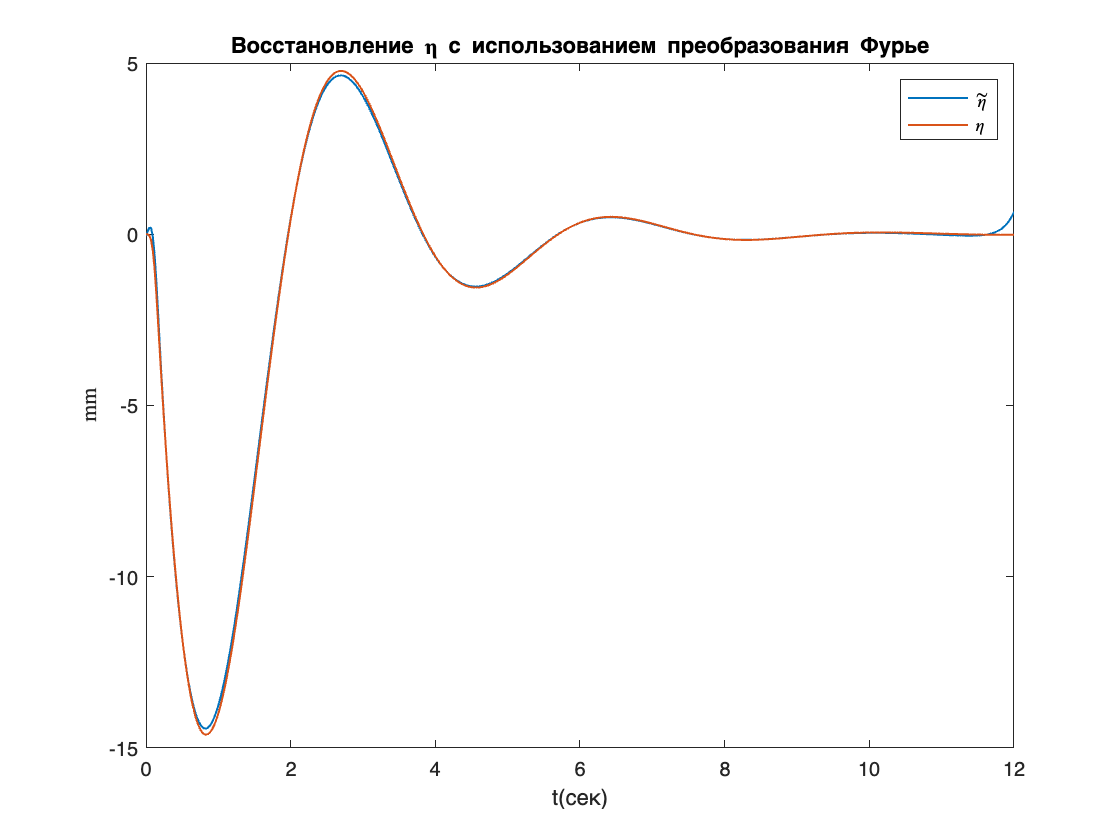

plot(t,afterfur2,t,realeta,'LineWidth',1);
title("Восстановление \eta с использованием преобразования Фурье")
xlabel("t(сек)");ylabel('mm','Interpreter','latex')
legend('$\tilde{\eta}$','$\eta$','Interpreter','latex')

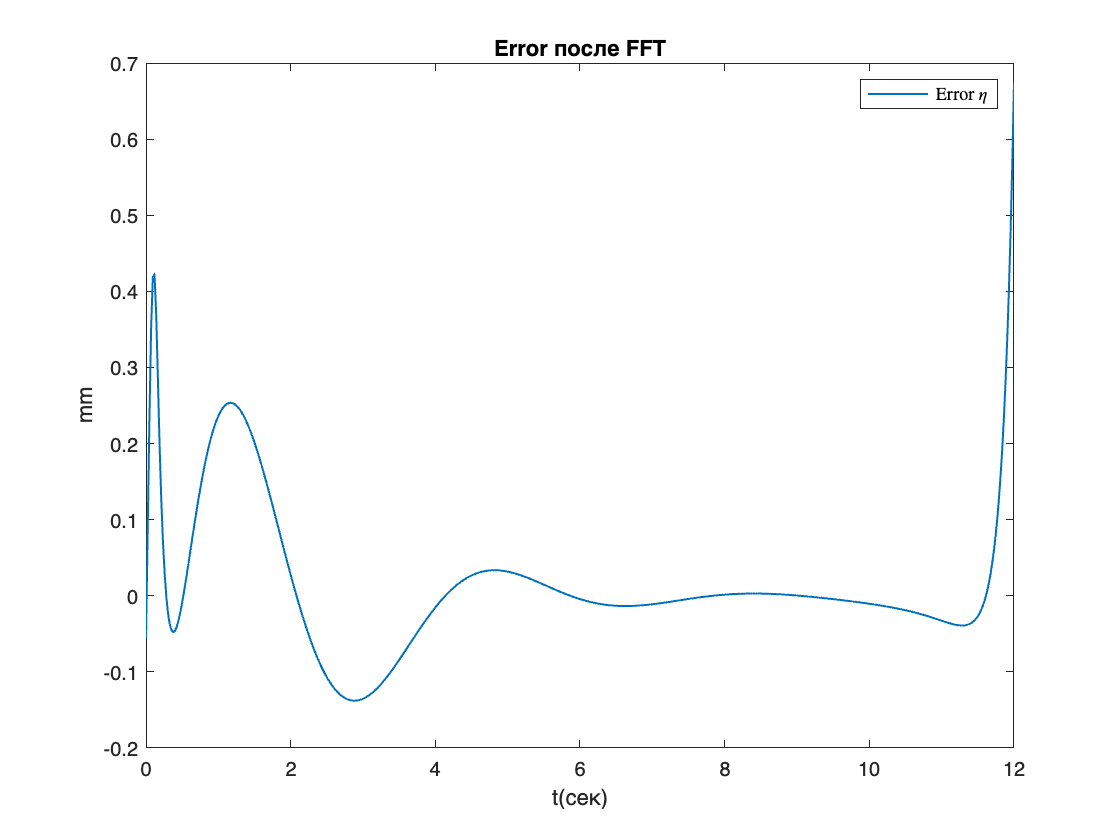


plot(t,afterfur2'-realeta,'LineWidth',1);
title("Error после FFT")
xlabel("t(сек)");ylabel('mm')
legend('Error $\eta$','Interpreter','latex')

rmse1=sqrt(mean((afterfur2' - realeta).^2))

rmse1 = 0.1015

# Поиск \eta, зная Y через фильтрацию

numerator=1;
denominator=[sqrt((J)/(m*g*l)) 1];
H = tf(numerator,denominator); 
Hd = c2d(H,12/512,'foh')

Hd =
 
  0.05082 z + 0.04907
  -------------------
      z - 0.9001
 
Sample time: 0.023438 seconds
Discrete-time transfer function.




miidledata=filter(cell2mat(Hd.numerator),cell2mat(Hd.denominator),ybase2);


numerator=1;
denominator=[sqrt((J)/(m*g*l)) 1];
H = tf(numerator,denominator); 
Hd2 = c2d(H,12/512,'foh')

Hd2 =
 
  0.05082 z + 0.04907
  -------------------
      z - 0.9001
 
Sample time: 0.023438 seconds
Discrete-time transfer function.



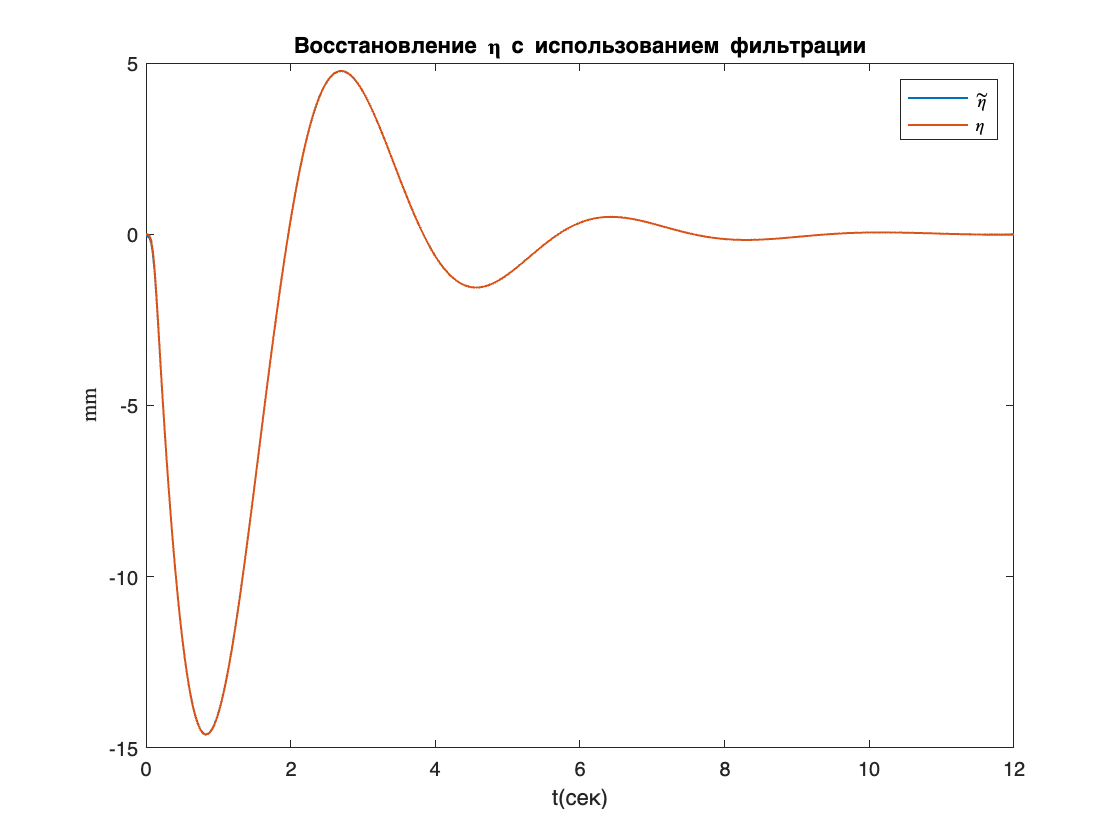


enddata=flip(filter(cell2mat(Hd2.numerator),cell2mat(Hd2.denominator),flip(miidledata)));

plot(t(1:ticks),enddata,t(1:ticks),realeta,'LineWidth',1);
title("Восстановление \eta с использованием фильтрации")
xlabel("t(сек)");ylabel('mm','Interpreter','latex')
legend('$\tilde{\eta}$','$\eta$','Interpreter','latex')

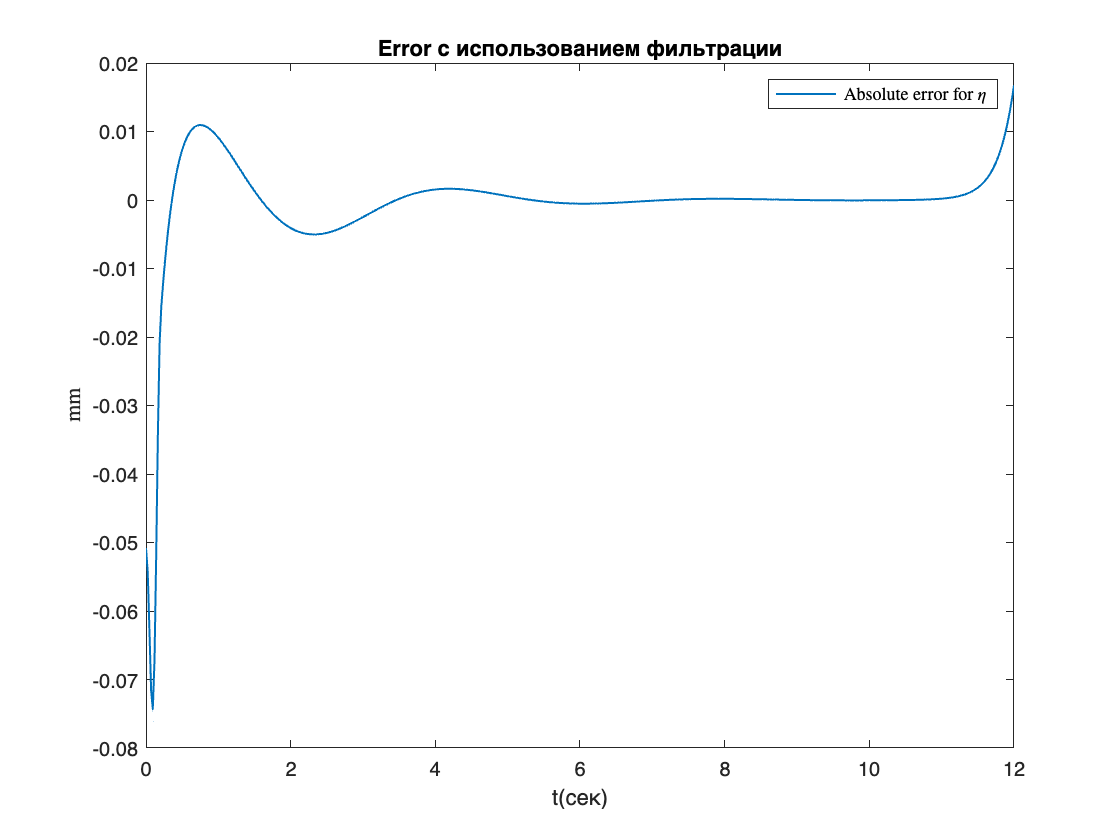


plot(t(1:ticks),enddata-realeta,'LineWidth',1);
title("Error с использованием фильтрации")
xlabel("t(сек)");ylabel('mm','Interpreter','latex')
legend('Absolute error for $\eta$','Interpreter','latex')

rmse2=sqrt(mean((enddata - realeta).^2))

rmse2 = 0.0083

function xn=COPMfftfilt(sy,N,J,mgh)

nt=(1:N)';
a=(sy(N)-sy(1))/(N-1);
b=(sy(N)-sy(1))/2;
x=sy(1:N)-a*nt-b;
f=(1:N)/N*50*2*pi;
kw=-mgh./(J*f(1:(N/2+1)).^2+mgh);
S=fft(x,N);
Sn=S(1:(N/2+1)).*kw';   
Sn((N/2+2):N)=flipud(conj(Sn(2:(N/2))));
xn=ifft(Sn)-a*nt-b;
xn=-1*xn;
end